- **CVar Portfolio Optimization**

clear; close all; clc; rng(0);

Retrieve data

load("dati.mat");

Select assets into portfolio

symbol = {'PII','NUVA','LQDT','FLR','CATY','ANF'};
nAsset = numel(symbol);

We pick the returns

ret = [PII.TotalReturn,NUVA.TotalReturn,LQDT.TotalReturn,FLR.TotalReturn,CATY.TotalReturn,ANF.TotalReturn];

Check the histogram of returns

plotAssetHist(symbol,ret)

## Simulate asset scenarios

Set number of scenarios and simulation method

nScenario = 2000;
simulationMethod = 'Normal'

simulationMethod = 'Normal'

switch simulationMethod
    case 'Normal'% Based on normal distribution
        AssetScenarios = mvnrnd(mean(ret),cov(ret),nScenario);
    case 'Empirical' % Based on empirical distribution using t-copula
        AssetScenarios = simEmpirical(ret,nScenario);
end

Check the histogram of asset scenarios

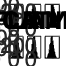

plotAssetHist(symbol,AssetScenarios)

## CVaR Portfolio Optimization

 Construct a fully invested long only portfolio using `PortfolioCVaR` object

p1 = PortfolioCVaR('Scenarios', AssetScenarios);
p1 = setDefaultConstraints(p1); 
p1 = setProbabilityLevel(p1, 0.95);

Plot efficient frontier and calculate portfolio weights

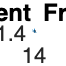

figure;
w1 = estimateFrontier(p1);
plotFrontier(p1,w1);

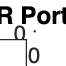

plotWeight(w1, symbol, 'CVaR Portfolio');

## **Visualize histogram of portfolio returns**

Select the portfolio number and plot histogram with the red bars representing the returns that are lower than VaR Level

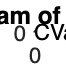

portNum = 5; % Select port number in figure above
plotCVaRHist(p1, w1, ret, portNum, 50)

## Mean-Variance Portfolio Optimization

Construct portfolio using `Portfolio` object

p2 = Portfolio;
p2 = setAssetList(p2, symbol);
p2 = estimateAssetMoments(p2, ret);
p2 = setDefaultConstraints(p2);

Plot efficient frontier and calculate portfolio weights

w2 = estimateFrontier(p2);
plotFrontier(p2,w2);
plotWeight(w2, symbol, 'Mean-Variance Portfolio ');

## CVaR VS Mean-Variance Portfolio Optimization

Estimate the CVaR and return of portfolios

pRet1 = estimatePortReturn(p1,w1);
pRisk1 = estimatePortRisk(p1,w1);
pRet2 = estimatePortReturn(p1,w2);
pRisk2 = estimatePortRisk(p1,w2);

Plot mean-CVaR efficient frontiers

figure
plot(pRisk1,pRet1,'-r',pRisk2, pRet2,'--b')
title('Efficient Frontiers (CVaR VS Mean-Variance)');
xlabel('Conditional Value-at-Risk of Portfolio');
ylabel('Mean of Portfolio Returns');
legend({'CVaR','Mean-Variance'},'Location','southeast')

Compare the portfolio weights of both methods

plotWeight2(w1, w2, symbol)

# Supporting Functions

**Simulate empirical asset scenarios**

You can also see the example in the documentation [here](https://www.mathworks.com/help/stats/copulas-generate-correlated-samples.html).

function AssetScenarios = simEmpirical(ret,nScenario)

Transform the data to the copula scale (unit square) using a kernel estimator of the cumulative distribution function.

[nSample,nAsset] = size(ret);
u = zeros(nSample,nAsset);
for i = 1:nAsset
    u(:,i) = ksdensity(ret(:,i),ret(:,i),'function','cdf');
end

Fit a *t *copula to the data.

[rho, dof] = copulafit('t',u);

Generate a random sample from the copula.

r = copularnd('t',rho,dof,nScenario);

Transform the random sample back to the original scale of the data.

AssetScenarios = zeros(nScenario,nAsset);
for i = 1:nAsset
    AssetScenarios(:,i) = ksdensity(ret(:,i),r(:,i),'function','icdf');
end
end

**Plot  histogram of underlying assets**

function plotAssetHist(symbol,ret)
figure
nAsset = numel(symbol);
plotCol = 3;
plotRow = ceil(nAsset/plotCol);
for i = 1:nAsset
    subplot(plotRow,plotCol,i);
    histogram(ret(:,i));
    title(symbol{i});
end
end

**Plot CVaR histogram**

function plotCVaRHist(p, w, ret, portNum, nBin)
% This function is used to plot histogram of returns by 
% highlighting the bins with value lower than VaR in red 
% using the vertical line to indicate the CVaR level

% portfolio returns given portNum
portRet = ret*w(:,portNum); 

% Calculate VaR and CVaR of the portfolios.
VaR = estimatePortVaR(p,w(:,portNum));
CVaR = estimatePortRisk(p,w(:,portNum));

% Convert positive number to negative number
VaR = -VaR; 
CVaR = -CVaR;

% Plot main histogram
figure;
h1 = histogram(portRet,nBin);
title('Histogram of Returns');
xlabel('Returns')
ylabel('Frequency')
hold on;

% Highlight bins with lower edges < VaR level in red
edges = h1.BinEdges;
counts = h1.Values.*(edges(1:end-1) < VaR);
h2 = histogram('BinEdges',edges,'BinCounts',counts);
h2.FaceColor = 'r';

% Add CVaR line
plot([CVaR;CVaR],[0;max(h1.BinCounts)*0.80],'--r')

% Add CVaR text
text(edges(1), max(h1.BinCounts)*0.85,['CVaR = ' num2str(round(-CVaR,4))])
hold off;
end

**Plot portfolio weights**

function plotWeight(w, symbol, title1)
% This function is used to plot portfolio weights 
% for each portfolio number (scenarios)

figure;
w = round(w'*100,1);
area(w);
ylabel('Portfolio weight (%)')
xlabel('Port Number')
title(title1);
ylim([0 100]);
legend(symbol);
end

**Plot portfolio weight CVaR VS Mean-Variance**

function plotWeight2(w1, w2, symbol)
figure;
subplot(1,2,1)
w1 = round(w1'*100,1);
area(w1);
ylabel('Portfolio weight (%)')
xlabel('Port Number')
title('CVaR');
xlim([1 10])
ylim([0 100]);
legend(symbol);

subplot(1,2,2)
w2 = round(w2'*100,1);
area(w2);
ylabel('Portfolio weight (%)')
xlabel('Port Number')
title('Mean-Variance');
xlim([1 10])
ylim([0 100]);
legend(symbol);
end
